# Disturbance Estimation

clear
close all

Define system matrices

A = [1/2 -1/4; 1/4 1/2];
C = eye(2);

## Estimator design

Augmented system: $\left[\matrix{ 
\hat{x}(k\!+\!1) \cr \hat{d}(k\!+\!1)}\right] =
\left[\matrix{ 
A & I  \cr 0 & I }\right] \left[\matrix{ 
\hat{x}(k) \cr \hat{d}(k)}\right] + \left[\matrix{ 
B \cr 0}\right] u(k) + \left[\matrix{L_x \cr L_d}\right]\left[C \ 0\right]\left(\left[\matrix{ 
\hat{x}(k) \cr \hat{d}(k)}\right] - \left[\matrix{ 
x(k) \cr d(k)}\right]\right)$

Error dynamics: $\left[\matrix{x(k\!+\!1)-\hat{x}(k\!+\!1)\cr d-\hat{d}(k\!+\!1)}\right] =
\left(\left[\matrix{A & I  \cr 0 & I }\right] + 
\left[\matrix{L_x \cr L_d}\right]
\left[I \ 0\right] \right)
\left[\matrix{x(k\!)-\hat{x}(k\!)\cr d-\hat{d}(k\!)}\right]

$

Aaug = [A, eye(2); zeros(2), eye(2)]; 
Caug = [eye(2), zeros(2)];

Design estimator by pole placement (duality to controller design with $A^T + C^T L^T$)

$K=\mathrm{place}\left(A,B,P\right)$ computes $K$ such that $A-B\;K$ has eigenvalues as specified in $P$


$$A_e =A_{\mathrm{aug}} +L\;C_{\mathrm{aug}}$$



$$A_e^{\;T} ={\left(A_{\mathrm{aug}} +L\;C_{\mathrm{aug}} \right)}^T =A_{\mathrm{aug}}^{\;\;\;\;\;T} +C_{\mathrm{aug}}^{\;\;\;\;\;T} \;L^T =A_{\mathrm{aug}}^{\;\;\;\;\;T} -C_{\mathrm{aug}}^{\;\;\;\;\;T} \left(-L^T \right)$$
 

Run $-{\mathrm{place}\left(A_{\mathrm{aug}}^{\;\;\;\;\;T} ,C_{\mathrm{aug}}^{\;\;\;\;\;T} ,P\right)}^T$because $\mathrm{place}\left(A_{\mathrm{aug}}^{\;\;\;\;\;T} ,C_{\mathrm{aug}}^{\;\;\;\;\;T} ,P\right)$returns $-L^T$

P = [0,0,0.5,0.5];
L = -(place(Aaug',Caug',P))';

Check the resulting eigenvalues 

eig(Aaug + L*Caug)

ans =    -0.0000
    0.5000
   -0.0000
    0.5000


## Simulation

Nsim = 10; % simulation time steps

Specify initial conditions

x(:,1) = [1;1];
d = [0.1; -0.2];
xh(:,1) = [1;1];
dh(:,1) = [0;0];

Simulate autonomous system

aux = [xh(:,1); dh(:,1)];
for i = 1:Nsim-1
    x(:,i+1) = A*x(:,i) + d;
    aux = Aaug*aux + L*(Caug*aux - x(:,i));
    xh(:,i+1) = aux(1:2); dh(:,i+1) = aux(3:4);
end

Plot result

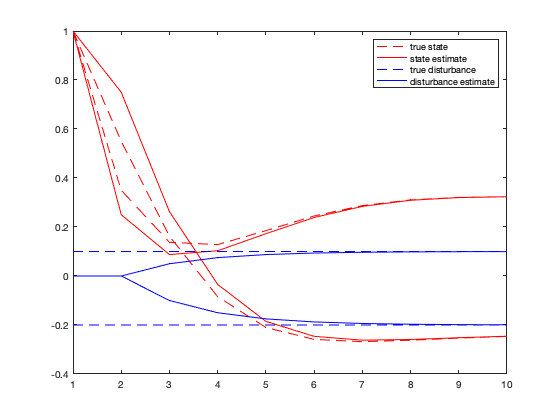

figure(1)
hold off
p1 = plot(x','r--');
hold on
p2 = plot(xh','r');
p3 = plot([1, Nsim],[d'; d'],'b--');
p4 = plot(dh','b');
legend([p1(1),p2(1),p3(1),p4(1)],'true state','state estimate','true disturbance','disturbance estimate');

## Alternative design

In the previous solution the estimate at time step k+1 makes use of the measured state at k. If you want the estimator to make use of the measured state k+1 you can do this by adjusting the C matrix


$$y(k) = x(k\!+\!1) = \underset{C}{\underbrace{A}} x(k) + d$$


Caug_alt = [A, eye(2)];
L_alt = -(place(Aaug',Caug_alt',[0,0,0.5,0.5]))';

## Simulation

x_alt(:,1) = [1;1];
xh_alt(:,1) = [1;1];
d = [0.1; -0.2];
dh_alt(:,1) = [0;0];


aux = [xh_alt(:,1); dh_alt(:,1)];
for i = 1:Nsim-1
    x_alt(:,i+1) = A*x_alt(:,i) + d;
    aux = Aaug*aux + L_alt*(Caug_alt*aux - x(:,i+1));   %using measurement x(k+1)
    xh_alt(:,i+1) = aux(1:2); dh_alt(:,i+1) = aux(3:4);
end

Plot results (estimated state is now equal to the measured state when correctly initialized)

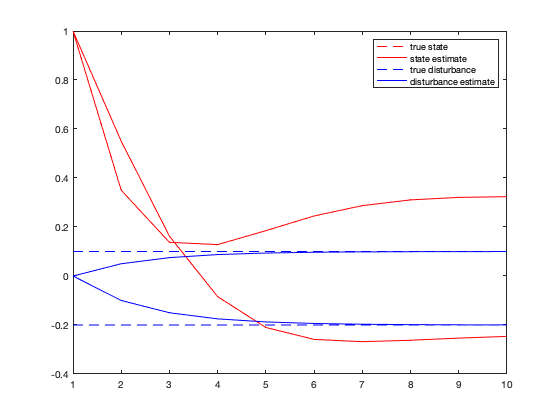

figure(2)
hold off
p1 = plot(x_alt','r--');
hold on
p2 = plot(xh_alt','r');
p3 = plot([1, Nsim],[d'; d'],'b--');
p4 = plot(dh_alt','b');
legend([p1(1),p2(1),p3(1),p4(1)],'true state','state estimate','true disturbance','disturbance estimate');